value_table = [0 2 4 6 8 10;
               10 20 0 30 40 40;
               0 -10 20 3 0 0
               0 5 10 3 0 0];
coef_table = zeros(size(value_table,2)-1,6);
for i = 1:size(value_table,2)-1
    h = value_table(1,i+1) - value_table(1,i);
    coef_mat = [1 0 0 0 0 0;
                1 h h^2 h^3 h^4 h^5;
                0 1 0 0 0 0;
                0 1 2*h 3*h^2 4*h^3 5*h^4;
                0 0 2 0 0 0;
                0 0 2 6*h 12*h^2 20*h^3];
    value_vec = [value_table(2,i) value_table(2,i+1) value_table(3,i) value_table(3,i+1) value_table(4,i) value_table(4,i+1)].';
    coef_table(i,:) = (coef_mat\value_vec).';
end
coef_table

coef_table =    10.0000         0    0.0000   23.7500  -19.3750    4.0625
   20.0000  -10.0000    2.5000  -31.2500   25.6250   -5.3125
         0   20.0000    5.0000   -2.2500   -2.5000    0.8750
   30.0000    3.0000    1.5000    5.7500   -5.2500    1.1250
   40.0000         0         0         0         0         0


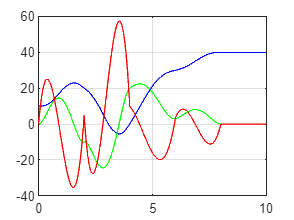

for i = 1:size(value_table,2)-1
    x = linspace(value_table(1,i+1),value_table(1,i));
    tk = value_table(1,i);
    ak = coef_table(i,1);
    bk = coef_table(i,2);
    ck = coef_table(i,3);
    dk = coef_table(i,4);
    ek = coef_table(i,5);
    fk = coef_table(i,6);
    y1 = ak + bk * (x - tk) + ck * (x - tk).^2 + dk * (x - tk).^3 + ek * (x - tk).^4 + fk * (x - tk).^5;
    y2 = bk + 2 * ck * (x - tk) + 3 * dk * (x - tk).^2 + 4 * ek * (x - tk).^3 + 5 * fk * (x - tk).^4;
    y3 = 2 * ck + 6 * dk * (x - tk) + 12 * ek * (x - tk).^2 + 20 * fk * (x - tk).^3;
    plot(x,y1,'b',x,y2,'g',x,y3,'r');
    hold on;
end
grid on;
hold off;